# Smoothing and filtering

Minilecture ONWAR Matlab course

2017-2020, Alexander Heimel

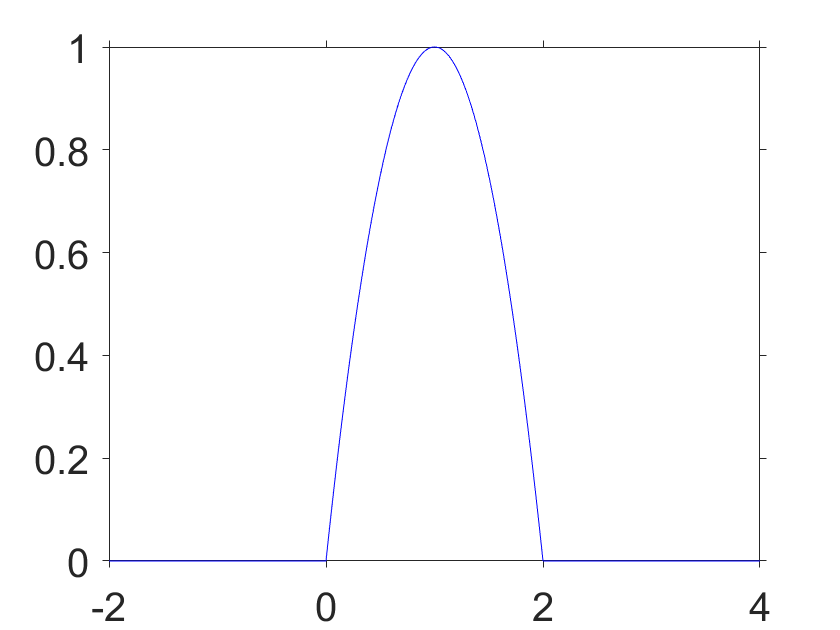

Fs = 1000; % Hz, sampling frequency

t = -2:1/Fs:4; % time (s)

thresholdlin = @(x) max(0,x);

signal =  thresholdlin(-t.*(t-2));
hold off
plot(t,signal,'b')

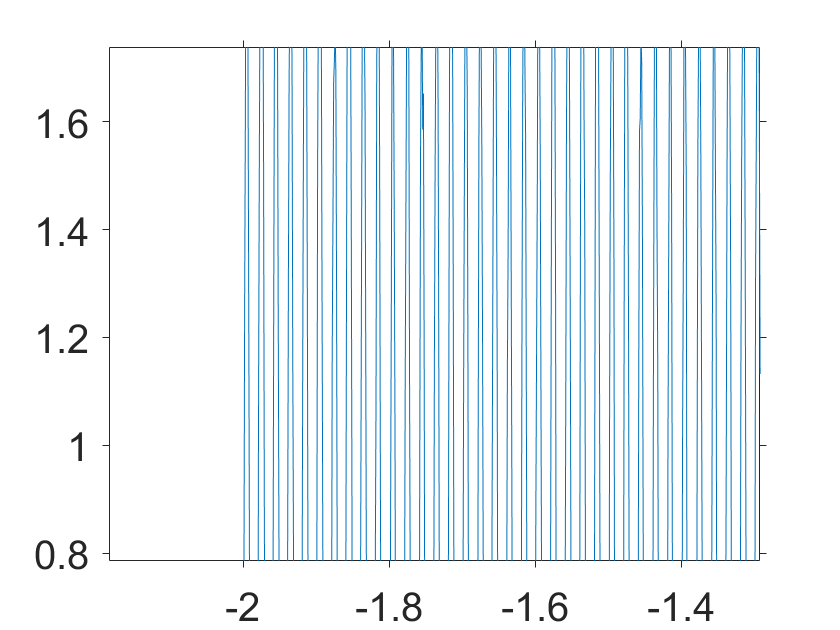


linenoise = 2*sin(t * 2*pi*50);  % 50 Hz noise from the mains, 

whitenoise = (rand(size(signal))-0.5); % broadband 

pinknoise = dsp.ColoredNoise('Color','pink','SamplesPerFrame',length(t)); % 1/f power

r = signal + linenoise  + 0.1 * whitenoise + 0.1 * pinknoise()';
plot(t,r)
hold on

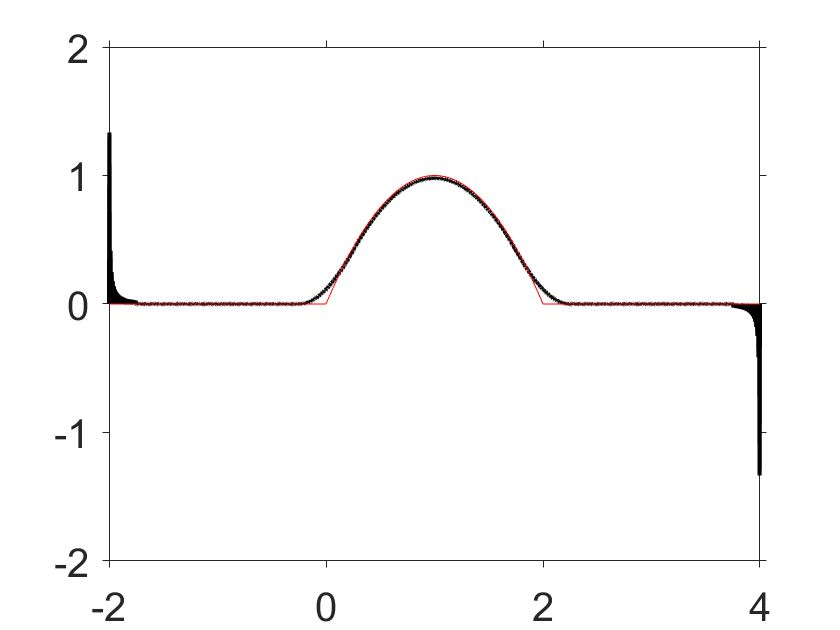

% smoothing, averaging window 0.5 s
r = signal + linenoise;
figure
plot(t,smooth(r,0.5*Fs)','k','linewidth',2)
hold on
plot(t,signal,'r')

% works well but onset moves forward in time
% also note edge effects

hold off

Frequency filtering

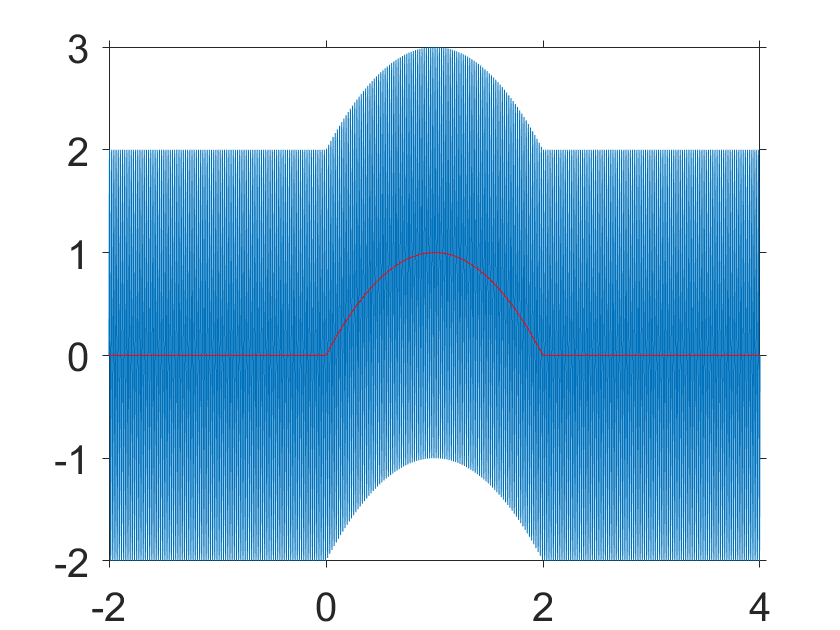


r = signal + linenoise ; %+ whitenoise; % + pinknoise()';
figure
plot(t,r)
hold on
plot(t,signal,'r')
hold off

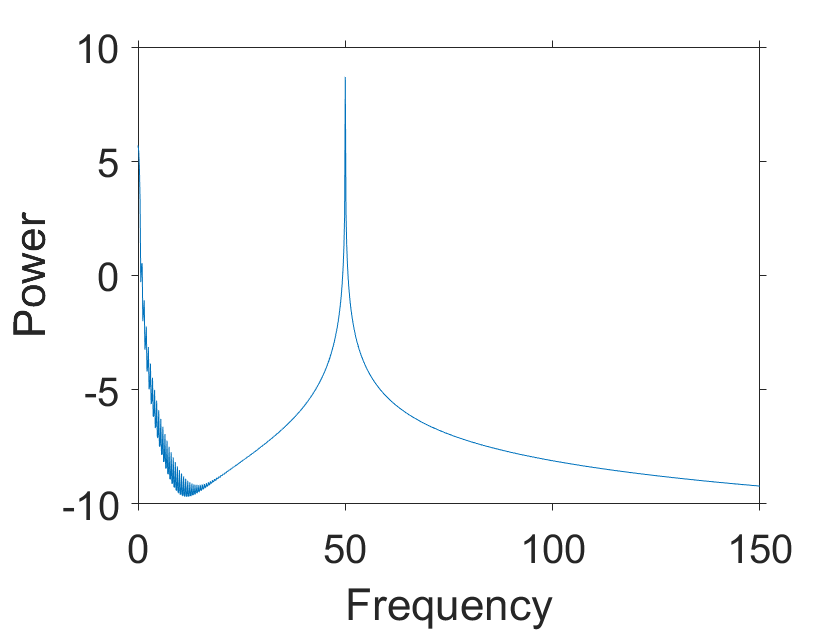

y = fft(r);             % fourier transform
n = length(r);          % number of samples
f = (0:n-1)*(Fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT

plot(f,log(power))
xlim([0 150])
xlabel('Frequency')
ylabel('Power')

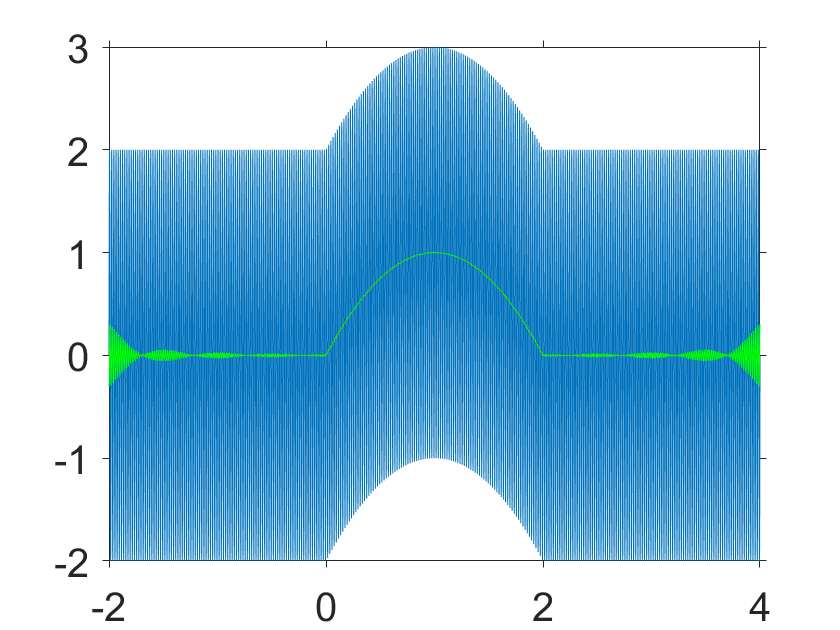

% remove 50 Hz frequency component
ind = find( (f>49 & f<51) | (f>(max(f)-51) & f<(max(f)-49)));
y(ind) = 0;
rf = real(ifft(y));

plot(t,r)
hold on
plot(t,signal,'r')
plot(t,rf,'g')
hold off

Notch filter = blocks a specific frequency (usually 50 or 60 Hz)

Low pass filter = lets low frequencies pass (survive)

High pass filter = lets high frequencies pass

Band pass filter = lets a specific band pass

## Matlab filter and filtfilt function

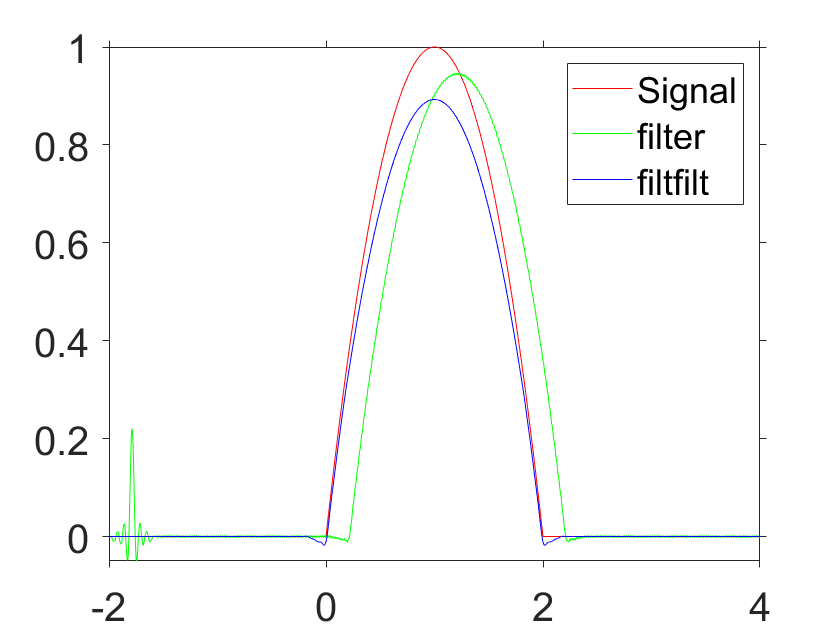

d = designfilt('lowpassfir', ...
    'PassbandFrequency',30/Fs,'StopbandFrequency',40/Fs, ...
    'PassbandRipple',1,'StopbandAttenuation',60, ...
    'DesignMethod','equiripple');
y1 = filter(d,r); % delayed
y = filtfilt(d,r); % two-pass
plot(t,signal,'r');
hold on
plot(t,y1,'g')
plot(t,y,'b')
legend('Signal','filter','filtfilt');